# Egg Money

## Read Data & Clean up Table

clear;clc;
data = readtimetable('Transactions-perscap.csv','TextType',"string");
data.Amount = -1 * data.Amount;

## Select Pet Expenses

pet_supplies = data.Category=="Pets/Pet Care";
vet_bills = contains(data.Description,["Framingham Animal Hospital"]);
pet_expenses = data(pet_supplies | vet_bills,:);

## All Spending on Egg

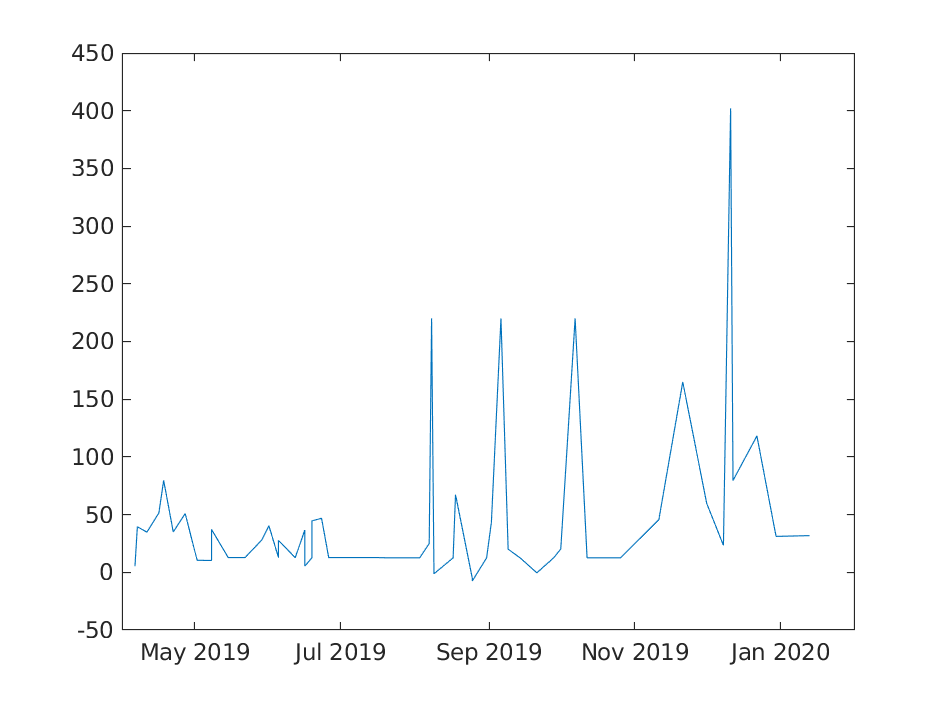

plot(pet_expenses.Date,pet_expenses.Amount)

## Monthly Data


pet_expenses = splitAndAddDates(pet_expenses);
pet_expenses = pet_expenses (pet_expenses.yy == 2019,:);

[g,ID] = findgroups(pet_expenses.mm);
monthSum = splitapply(@sum,pet_expenses.Amount,g);
monthAvg = splitapply(@mean,pet_expenses.Amount,g);

hold on


plot(ID,monthAvg,'-x');

Values plotted against x-axis must be datetime values. To create datetime values, use the datetime function.

grid on;
legend('average','sum');
xlabel("Month")
ylabel("Spending")
title("Monthly Spending")
hold off



function pet_expenses = splitAndAddDates(pet_expenses)
[yy,~,dd] = ymd(pet_expenses.Date);
mm = categorical(month(pet_expenses.Date,'name'));
pet_expenses = addvars(pet_expenses,yy,mm,dd);
end